Задание 1. Кластеризация соц. сети.

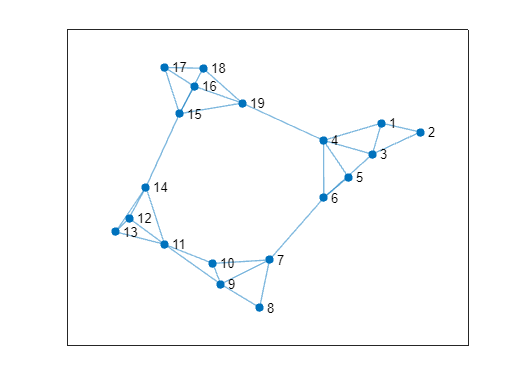

% Начальный граф
s = [1 1 1 2 3 3 4 4 4  5 6 7 7 7  8 9  9  10 11 11 11 12 12 13 14 15 15 15 15 16 16 17 18];
t = [2 3 4 3 4 6 6 5 19 6 7 8 9 10 9 10 11 11 12 13 14 13 14 14 15 16 17 18 19 17 19 18 19];
G = graph(s,t);
g0 = plot(G);
hold off

V_1 = [
1
1
1
1
1
1
1
1
1
1
1
1
1
1
1
1
1
1
1];
V_2 = [
 6.196
 6.860
 5.602
 4.390
 4.526
 3.395
-1.891
-3.176
-3.572
-3.679
-4.543
-5.036
-5.036
-4.119
-0.705
 0.018
-0.246
 0.018
     1];
V_3 = [
-0.414
-0.510
-0.431
-0.157
-0.394
-0.494
-0.826
-0.980
-0.797
-0.747
-0.361
-0.136
-0.136
 0.135
 1.129
 1.342
 1.436
 1.342
     1];
V_4 = [
-1.759
-2.512
-1.147
-0.135
 0.561
 0.784
 3.197
 4.970
 2.553
 1.787
-1.896
-4.472
-4.472
-3.277
 0.493
 1.400
 1.526
 1.400
     1];
V_5 = [
-10.483
-21.649
 -4.151
  8.231
 31.100
 12.792
 -0.950
 -7.885
 -4.380
 -3.070
  0.185
  3.107
  3.107
  1.915
 -1.273
 -2.141
 -3.315
 -2.141
      1];
X=cat(2,V_1,V_2,V_3,V_4,V_5); % Матрица собственных векторов
idx = kmeans(X,5); % Вектор кластеризации по k


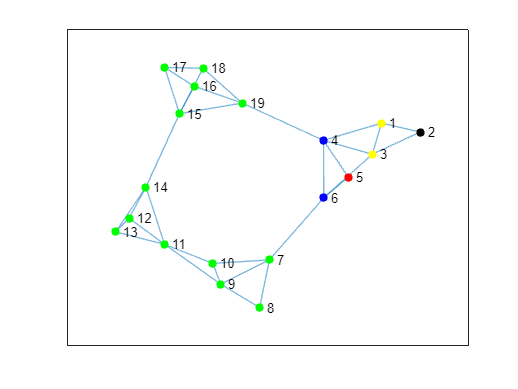

for i = 1:1:19 % Изменяем цвет узлов в каждом кластере
    if idx(i) == 1
        highlight(g0,i,'NodeColor','green');
    elseif idx(i) == 2
        highlight(g0,i,'NodeColor','red');
    elseif idx(i) == 3
        highlight(g0,i,'NodeColor','blue');
    elseif idx(i) == 4
        highlight(g0,i,'NodeColor','black');
    elseif idx(i) == 5
        highlight(g0,i,'NodeColor','yellow');
    end
end